clear;close all;
%-----------------------------------
%初始化
%nPoint：采样点数
%z0：设定的距离
%sigma：波数
%色散相位：-4*pi*((b0+z0)+b1*sigma).*sigma;
%-----------------------------------
nPoint = 2^18;
z0 = 10;
b0 = 35;
b1 = -10;
sigma = 0:(3/1024):(nPoint-1)*(3/1024);
% sigma = 0:0.0038*1024/1024:(nPoint-1)*0.0038*1024/1024;
%加窗 window1
window1 = ones(1,1024);
fSigma = fitfSigma(sigma);
fSigma = sigmult(fSigma,1:2^18,window1,1:2^10);
pSigma=-4*pi*((b0+z0)+b1*sigma).*sigma;
pSigma = sigmult(pSigma,1:2^18,window1,1:2^10);
iSigma = fSigma.*exp(1i*pSigma);
disp("光谱")

光谱


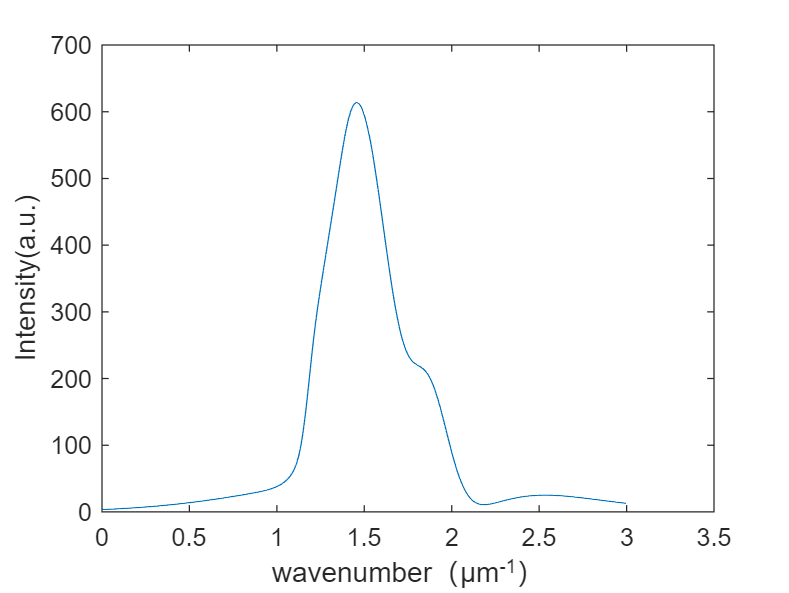

plot(sigma(1:2^10),fSigma(1:2^10));
xlim([0 3.5]);
xlabel('wavenumber（\mum^{-1}）')
ylabel('Intensity(a.u.)')

disp("有色散噪声的相位")

有色散噪声的相位


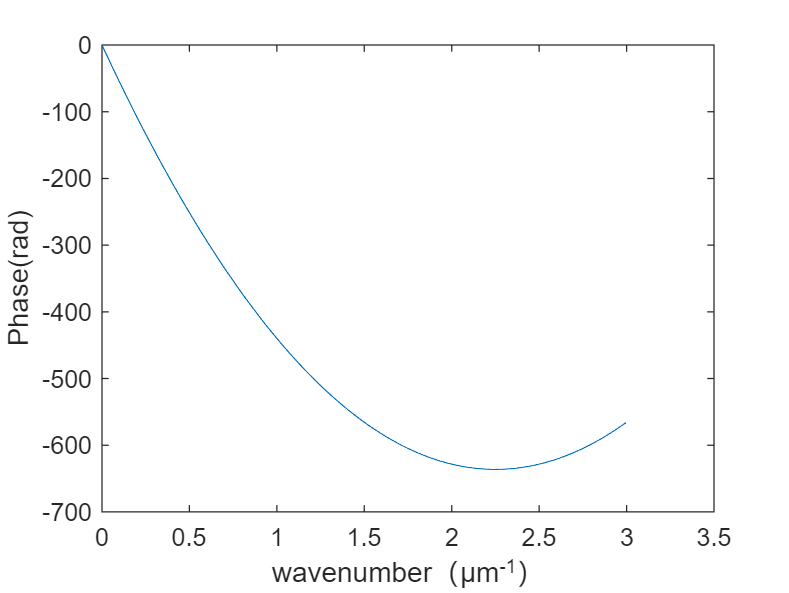

plot(sigma(1:2^10),pSigma(1:2^10));
xlim([0 3.5]);
xlabel('wavenumber（\mum^{-1}）')
ylabel('Phase(rad)')

%-----------------------------------
%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
powerTotal = 0;
for n=1:1:nPoint
    powerTotal=powerTotal+fSigma(n);
end
p = 0;
for n=1:1:nPoint
    p = p+ fSigma(n)*sigma(n);
end
lambdaA = powerTotal/p;

%-----------------------------------
%最小二乘法拟合
%LSM：最小二乘曲线
%-----------------------------------
coefficient1=polyfit(sigma(1:2^10),pSigma(1:2^10),1);
wrapToPi(coefficient1(2));
plot(sigma(1:2^10),pSigma(1:2^10));
LSM=polyval(coefficient1,sigma);
hold on
disp("作最小乘")

作最小乘


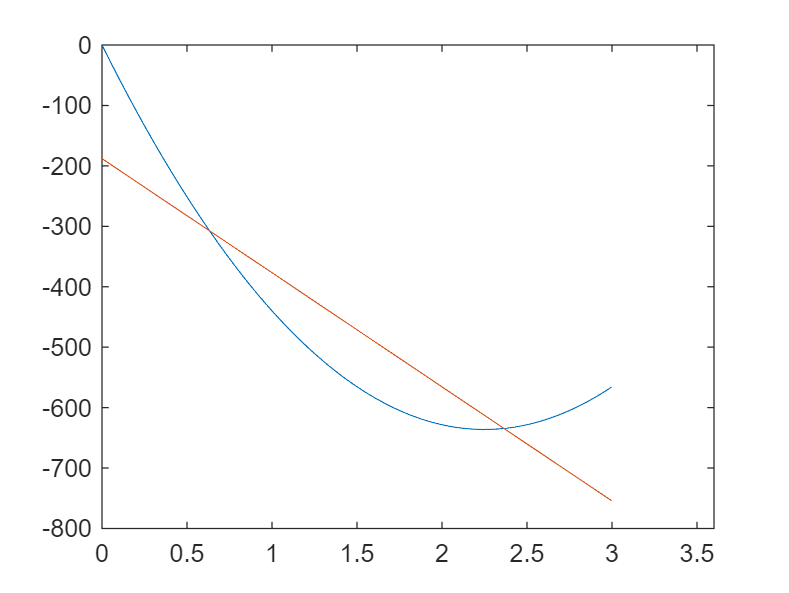

plot(sigma(1:2^10),LSM(1:2^10));
xlim([0 3.6])
hold off


%-----------------------------------
%IFFT运算
%deltaZ：z域的步长
%intensity：IFFT运算得到的振幅分布
%phase：IFFT运算得到的相位分布
%zData(index)：振幅最大的z值
%phase(index)：振幅最大的p值
%-----------------------------------
deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase = (angle(ifftIsigma));
%找到振幅最大值
[max1,index]= max(intensity);
zData(index)

ans = 15.8092

phase(index)

ans = -3.0968

disp("未作最小二乘的FFT后的振幅分布")

未作最小二乘的FFT后的振幅分布


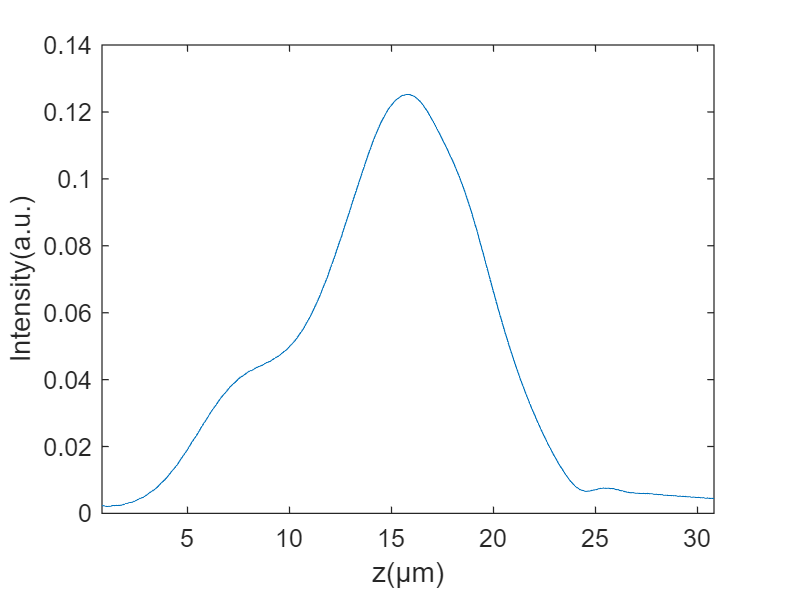

plot(zData,intensity);
xlim([zData(index)-15 zData(index)+15]);
xlabel('z(\mum)')
ylabel('Intensity(a.u.)')

disp("未作最小二乘的FFT后的相位分布")

未作最小二乘的FFT后的相位分布


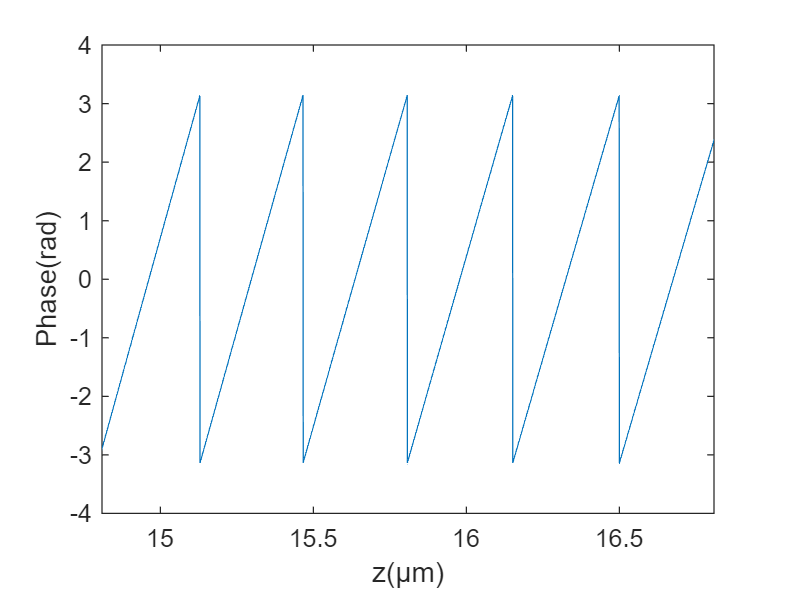

plot(zData,phase);
xlim([zData(index)-1 zData(index)+1]);
xlabel('z(\mum)')
ylabel('Phase(rad)')

%-----------------------------------
%IFFT运算（LSM）
%deltaZ：z域的步长
%intensity：IFFT运算得到的振幅分布
%phase：IFFT运算得到的相位分布
%zData(index1)：振幅最大的z值
%phase(index1)：振幅最大的p值
%-----------------------------------
fSigma = fitfSigma(sigma);
fSigma = sigmult(fSigma,1:2^18,window1,1:2^10);
pSigma = sigmult(LSM,1:2^18,window1,1:2^10);
iSigma = fSigma.*exp(1i*pSigma);
disp("最小二乘的相位分布")

最小二乘的相位分布


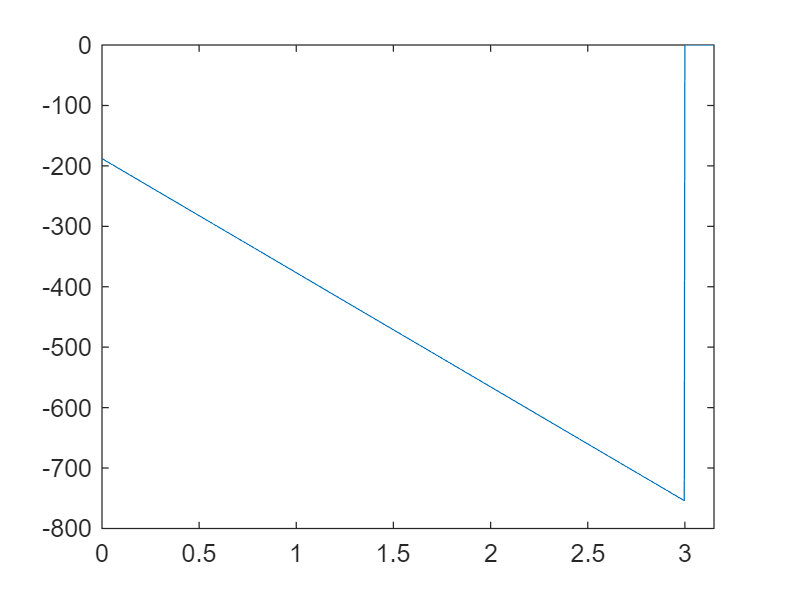

plot(sigma,pSigma);
xlim([0 2^10*(3.25/1024)-0.1]);

disp("最小二乘的振幅分布（光谱）")

最小二乘的振幅分布（光谱）


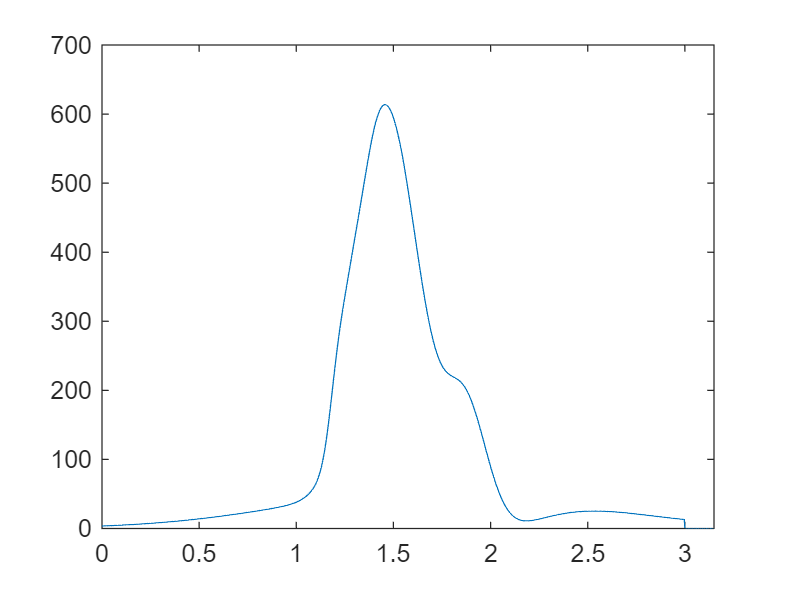

plot(sigma,fSigma);
xlim([0 2^10*(3.25/1024)-0.1]);

deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity1 = abs(ifftIsigma);
phase = (angle(ifftIsigma));
[max2,index2]= max(intensity1);
disp("作最小二乘的FFT后的振幅分布")

作最小二乘的FFT后的振幅分布


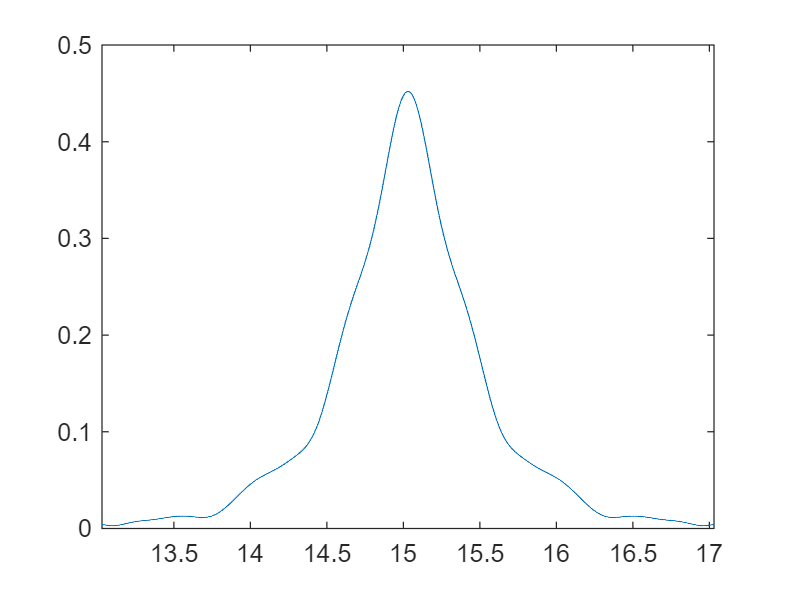

plot(zData,intensity1);
xlim([zData(index2)-2 zData(index2)+2]);

disp("作最小二乘的FFT后的相位分布")

作最小二乘的FFT后的相位分布


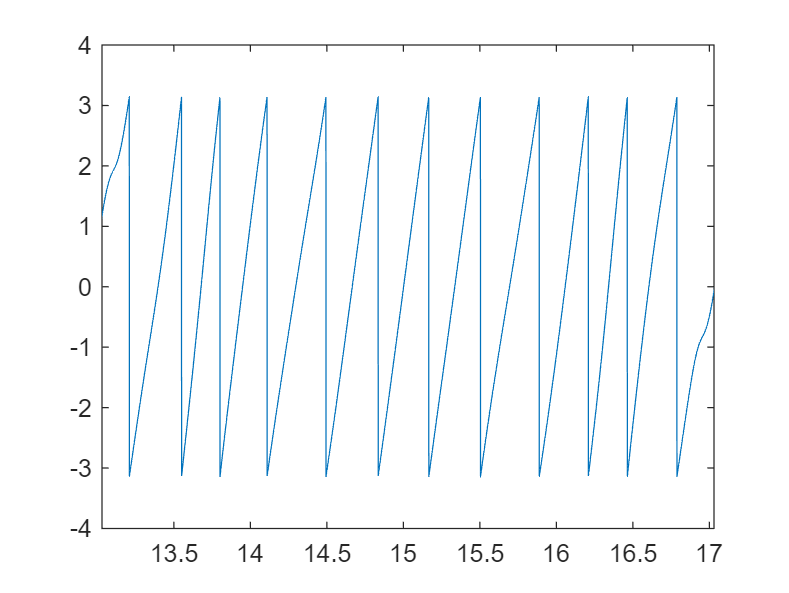

plot(zData,phase);
xlim([zData(index2)-2 zData(index2)+2]);

%找到振幅最大值
[max11,index1]= max(intensity1);
za1 = zData(index1);
phase(index1);

%-----------------------------------
%公式计算振幅最大及相位零值
%za：振幅最大值
%zp：相位零值
%-----------------------------------
a1=coefficient1(1)+4*pi*z0;
a0=wrapToPi(coefficient1(2));
za=z0-(a1/(4*pi));
zp=z0-((a1+a0*lambdaA)/(4*pi));

%-----------------------------------
%仿真计算振幅最大及相位零值
%za1：振幅最大值
%zp1：相位零值
%-----------------------------------
unwrapZend = zData(abs(zData-(za1+0.5))<0.001);
unwrapZ_1 = zData(abs(zData-(za1-0.5))<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = index1;
unwrapNe = find(zData==unwrapZend(end));
unwrapN_1 = find(zData==unwrapZ_1(1));
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index1);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
coefficient=polyfit(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe),1); 
LSM1=polyval(coefficient,zData(unwrapN_1:unwrapNe));
hold on 
disp("相位解包裹");

相位解包裹


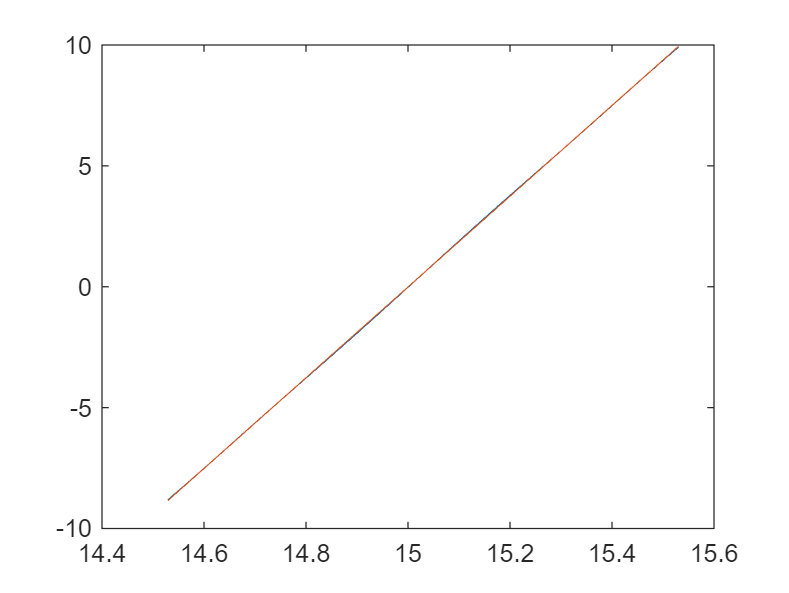

plot(zData(unwrapN_1:unwrapNe),LSM1);

phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
if za<0 && zp<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)
za1 = za1-zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N;
za1;
end
zadiff = za1-za

zadiff = 6.5104e-04

zpdiff = zp1-zp

zpdiff = 6.3983e-04


%-----------------------------------
%输出计算结果到表格
%-----------------------------------
outResult = 'outResult.xlsx';
%第一行
str1 = {'σA','Zo','λA'};
table1 = table(str1);
writetable(table1,outResult,'WriteVariableNames',false,'Sheet','Sheet1','Range','A1');
%第二行
str2 = {1/lambdaA,z0,lambdaA};
table2 = table(str2);
writetable(table2,outResult,'WriteVariableNames',false,'Sheet','Sheet1','Range','A2');
%第三行
str3 = {'b0','b1','a1','a0','ZaT','ZpT','ZaS','ZpS'};
table3 = table(str3);
writetable(table3,outResult,'WriteVariableNames',false,'Sheet','Sheet1','Range','A4');
%第四行
str4 = {b0,b1,a1,a0,za,zp,za1,zp1};
table4 = table(str4);
writetable(table4,outResult,'WriteVariableNames',false,'Sheet','Sheet1','Range','A5');
%第五行
str5 = {'b0','b1','P - λA/2','ZaS - ZaT','ZpS - ZpT'};
table5 = table(str5);
writetable(table5,outResult,'WriteVariableNames',false,'Sheet','Sheet1','Range','A7');
%第六行
str6 = {b0,b1,10,zadiff,zpdiff};
table6 = table(str6);
writetable(table6,outResult,'WriteVariableNames',false,'Sheet','Sheet1','Range','A8');

function fSigma = fitfSigma(x)
%Coefficients (with 95% confidence bounds):
       a1 =       88.19  ;%(51.68, 124.7)
       b1 =       1.378  ;%(1.347, 1.409)
       c1 =      0.1243  ;%(0.0879, 0.1606)
       a2 =      0.9322  ;%(-1.209, 3.073)
       b2 =       1.542  ;%(1.518, 1.565)
       c2 =     0.01341  ;%(-0.02512, 0.05195)
       a3 =       69.18  ;%(-6.223, 144.6)
       b3 =        1.27  ;%(1.228, 1.312)
       c3 =     0.07202  ;%(0.03205, 0.112)
       a4 =       528.7  ;%(493.5, 563.8)
       b4 =       1.488  ;%(1.483, 1.494)
       c4 =      0.2199  ;%(0.2153, 0.2245)
       a5 =       62.39  ;%(-14.96, 139.7)
       b5 =       1.207  ;%(1.188, 1.225)
       c5 =     0.05735  ;%(0.04772, 0.06698)
       a6 =         181  ;%(163.3, 198.6)
       b6 =        1.87  ;%(1.867, 1.873)
       c6 =       0.158  ;%(0.153, 0.1629)
       a7 =      -60.41  ;%(-80.21, -40.6)
       b7 =        1.92  ;%(1.789, 2.051)
       c7 =      0.4102  ;%(0.3363, 0.4841)
       a8 =       57.07  ;%(54.59, 59.55)
       b8 =       1.735  ;%(1.728, 1.742)
       c8 =       1.039  ;%(1.023, 1.054)
     fSigma = a1*exp(-((x-b1)/c1).^2) + a2*exp(-((x-b2)/c2).^2) +... 
              a3*exp(-((x-b3)/c3).^2) + a4*exp(-((x-b4)/c4).^2) + ...
              a5*exp(-((x-b5)/c5).^2) + a6*exp(-((x-b6)/c6).^2) + ...
              a7*exp(-((x-b7)/c7).^2) + a8*exp(-((x-b8)/c8).^2);
end

function index = fitfPigma(x,sigma)
lamda = 1./sigma;
if x=="N_BK"
    index2 = (1.03961212*lamda.^2)./(lamda.^2-0.00600069867)+(1.01046945*lamda.^2)./(lamda.^2-103.560653)+...
        (0.231792344*lamda.^2)./(lamda.^2-0.0200179144)+1; 
    index = sqrt(abs(index2));
elseif x=="N_F2"
    index2 = (1.39757037*lamda.^2)./(lamda.^2-0.00995906143)+(0.159201403*lamda.^2)./(lamda.^2-0.0546931752)+...
        (1.268654300*lamda.^2)./(lamda.^2-119.2483460)+1; 
    index = sqrt(abs(index2));
elseif x=="N_SF11"
    index2 = (1.73759695*lamda.^2)./(lamda.^2-0.013188707)+(0.313747346*lamda.^2)./(lamda.^2-0.0623068142)+...
        (1.89878101*lamda.^2)./(lamda.^2-155.23629)+1; 
    index = sqrt(abs(index2));
elseif x=="LbS"
    index2 = (1.5039759*lamda.^2)./(lamda.^2-0.0740288^2)+(0.55069141*lamda.^2)./(lamda.^2-0.1216529^2)+...
        (6.5927379*lamda.^2)./(lamda.^2-20.072248^2)+1; 
    index = sqrt(abs(index2));
elseif x=="JHS" 
    index2 = 2.9713+(5.1891*10^(-5))./(1.2280*10^(-5)-lamda.^(-2))-4.2950*10^(-8).*lamda.^2;
    index = sqrt(abs(index2));
else 
    error("其他");
end
end